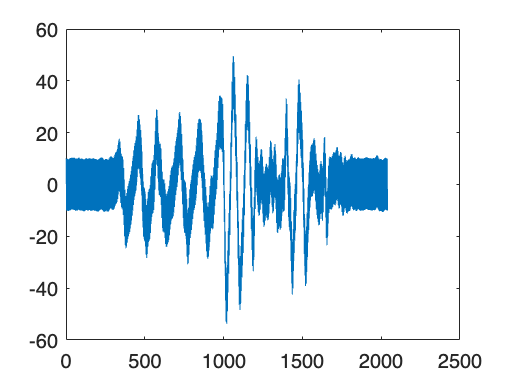

data = readtable('imu.txt');
plot(data.Var1);

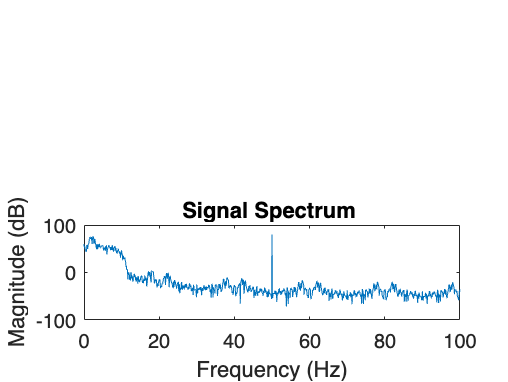

% Signal Parameters
Fs = 200; % Sampling frequency (Hz)
N = length(data.Var1); % Number of samples
T = 1/Fs; % Sampling period (s)
t = 0:T:(N/Fs)-T; % Time vector

%Perform FFT
D = abs(fft(data.Var1));
frequencies = (0:length(t)-1)*Fs/length(t); % Frequency vector

% Plot FFT of quantized sine wave
subplot(2,1,2);
plot(frequencies, 20*log10(D));
title('Signal Spectrum ');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
xlim([0 Fs/2]);


dF=filter(Hd, data.Var1);

Error using filter
Not enough input arguments.

plot(dF);
DF = abs(fft(dF));
plot(frequencies, 20*log10(DF));
xlim([0 Fs/2]);